# **Problem 1**

In this problem we are tasked with the implementation of the backprop algorithm for the presented neural network.

The ANN architecture presented in the problem statement is as follows:

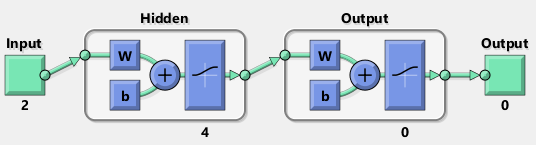

A 2-layer feedforward net that uses sigmoid as activation function for both layers. Due to the probabilistic nature of sigmoid and the fact that this network was designed to solve a two-class problem but with two output nodes, MSE loss was assumed.

The backpropgation algorithm for this problem can be broken down into the forward and the backward passes as follows:


$$\begin{array}{l}
h\left(X\right)=\mathrm{WX}+b\;\left(\mathrm{if}\;X\;\mathrm{is}\;\mathrm{augmented}\;\mathrm{for}\;b:WX\right)\\
a\left(z\right)=\sigma \left(z\right)=\frac{1}{1+e^{-z} }\\
\frac{\partial a\left(z\right)}{\partial z}=a\left(z\right)\left(1-a\left(z\right)\right)\\
L\left(\hat{y} \right)={\left(y-\hat{y} \right)}^T \left(y-\hat{y} \right)\\
\frac{\partial \;L\left(\hat{y} \right)}{\partial \hat{y} }=-2\left(y-\hat{y} \right)
\end{array}$$


## Forward Pass:


$$\begin{array}{l}
z_1 =W_1 X\\
a_1 =\frac{1}{1+e^{-z_1 } }\\
z_2 =W_2 a_1 \\
a_2 =\frac{1}{1+e^{-z_2 } }=\hat{y} \\
L\left(\hat{y} \right)={\left(y-\hat{y} \right)}^T \left(y-\hat{y} \right)
\end{array}$$


## Backward Pass:


$$\begin{array}{l}
S_2 ={\dot{F} }^2 \left(n^2 \right)\frac{\partial L\left(\hat{y} \right)}{\partial \hat{y} }\\
S_1 ={\dot{F} }^1 \left(n^1 \right){\left(W^2 \right)}^T S^2 
\end{array}$$


## Update Rules:


$$\begin{array}{l}
W^m \left(k+1\right)=W^m \left(k\right)-\eta S^m {\left(a^{m-1} \right)}^T \\
b^m \left(k+1\right)=b^m \left(k\right)-\eta S^m 
\end{array}$$


The implementation of this algorithm along with documentation is available in "MLP.mlx".

% loading the initial parameters, training and test sets

% datasets
% training set
X_train = readmatrix("Computer_Assignment_4_Data.xls","Sheet",2,"Range","B3:C1002")';
Y_train = readmatrix("Computer_Assignment_4_Data.xls","Sheet",2,"Range","D3:E1002")';
% testing set
X_test = readmatrix("Computer_Assignment_4_Data.xls","Sheet",3,"Range","B3:C1002")';
Y_test = readmatrix("Computer_Assignment_4_Data.xls","Sheet",3,"Range","A3:A1002")';

% hyperparameters
lr = readmatrix("Computer_Assignment_4_Data.xls","Sheet",1,"Range","C19:C19");
epochs = readmatrix("Computer_Assignment_4_Data.xls","Sheet",1,"Range","C20:C20");

% weights and biases
% W1
W1_init = zeros([4, 2]);
W1_init(:,1) = readmatrix("Computer_Assignment_4_Data.xls","Sheet",1,"Range","C5:C8");
W1_init(:,2) = readmatrix("Computer_Assignment_4_Data.xls","Sheet",1,"Range","C9:C12");
b1_init = readmatrix("Computer_Assignment_4_Data.xls","Sheet",1,"Range","C13:C16");
% W2
W2_init = zeros([2, 4]);
W2_init(:,1) = readmatrix("Computer_Assignment_4_Data.xls","Sheet",1,"Range","G5:G6");
W2_init(:,2) = readmatrix("Computer_Assignment_4_Data.xls","Sheet",1,"Range","G7:G8");
W2_init(:,3) = readmatrix("Computer_Assignment_4_Data.xls","Sheet",1,"Range","G9:G10");
W2_init(:,4) = readmatrix("Computer_Assignment_4_Data.xls","Sheet",1,"Range","G11:G12");
b2_init = readmatrix("Computer_Assignment_4_Data.xls","Sheet",1,"Range","G13:G14");

Now we will implement the training loop according to the calculations above:

[W1, W2, b1, b2, cost_hist] = MLP(X_train, Y_train, lr, epochs, W1_init, W2_init, b1_init, b2_init);

Loss at the end of epoch 100: 0.396114
Loss at the end of epoch 200: 0.321255
Loss at the end of epoch 300: 0.169184
Loss at the end of epoch 400: 0.119972
Loss at the end of epoch 500: 0.105833


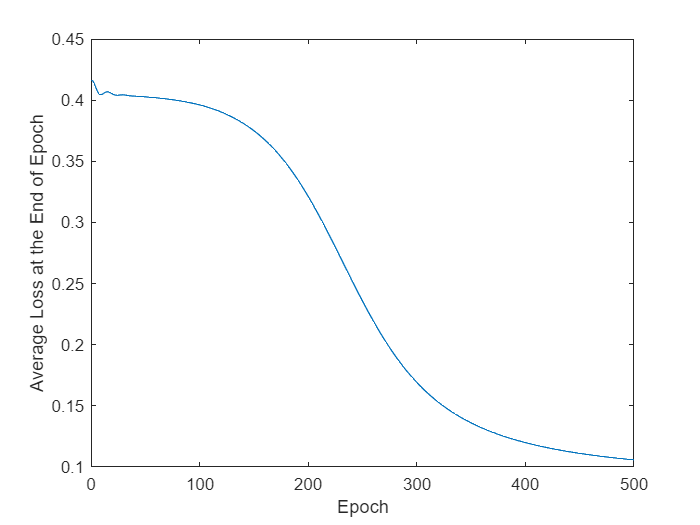

plot(cost_hist);
xlabel('Epoch')
ylabel('Average Loss at the End of Epoch')

As expected the loss is being reduced at the end of each epoch as we are headed in the general direction of the gradients that aim to minimize the cost function at every step. We will now write the final weights and biases to file. You can view them at "weights_and_biases_final.xlsx".

% write weights and biases to file
% W1
writematrix(W1(:,1), "weights_and_biases_final.xlsx","Sheet",1,"Range","C5:C8");
writematrix(W1(:,2), "weights_and_biases_final.xlsx","Sheet",1,"Range","C9:C12");
writematrix(b1, "weights_and_biases_final.xlsx","Sheet",1,"Range","C13:C16");
% W2
writematrix(W2(:,1), "weights_and_biases_final.xlsx","Sheet",1,"Range","G5:G6");
writematrix(W2(:,2), "weights_and_biases_final.xlsx","Sheet",1,"Range","G7:G8");
writematrix(W2(:,3), "weights_and_biases_final.xlsx","Sheet",1,"Range","G9:G10");
writematrix(W2(:,4), "weights_and_biases_final.xlsx","Sheet",1,"Range","G11:G12");
writematrix(b1, "weights_and_biases_final.xlsx","Sheet",1,"Range","G13:G14");

With the trained weights we will perform classification on the testing set and count the number of misclassified samples and draw up the confusion matrix.

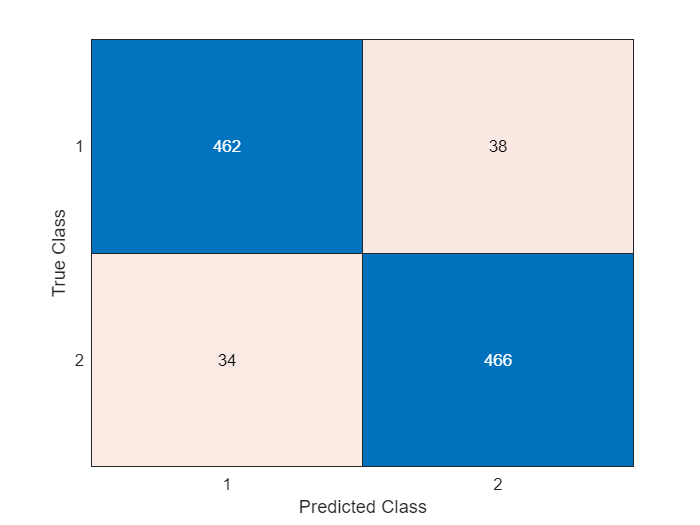

% Y_pred = argmax(prediction)
Y_pred_vals = logsig(W2*logsig(W1*X_test + b1) + b2);
[~, Y_pred] = max(Y_pred_vals);
% confusion matrix
confusionchart(Y_test, Y_pred);

error_indices = (Y_pred ~= Y_test);
fprintf('Number of misclassifications: %d\nError Rate: %f%%', sum(error_indices), 100*sum(error_indices)/length(Y_test));

Number of misclassifications: 72
Error Rate: 7.200000%

fprintf('Misclassified samples:\n');

Misclassified samples:


for i=1:length(error_indices)
    if error_indices(i)
        fprintf('Misclassified sample #%d. Actual class: %d, Predicted class: %d. Predictions:\n', i, Y_test(i), Y_pred(i));
        Y_pred_vals(:,i)
    end
end

Misclassified sample #11. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.4984
    0.5018


Misclassified sample #16. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.0817
    0.9150


Misclassified sample #25. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.4447
    0.5535


Misclassified sample #37. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.1847
    0.8116


Misclassified sample #56. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.4716
    0.5261


Misclassified sample #66. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.2388
    0.7570


Misclassified sample #94. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.2626
    0.7338


Misclassified sample #98. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.4235
    0.5750


Misclassified sample #120. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.3448
    0.6527


Misclassified sample #133. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.4240
    0.5759


Misclassified sample #134. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.4971
    0.5041


Misclassified sample #137. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.4900
    0.5089


Misclassified sample #148. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.2885
    0.7078


Misclassified sample #151. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.4378
    0.5604


Misclassified sample #154. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.3508
    0.6478


Misclassified sample #197. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.3856
    0.6127


Misclassified sample #211. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.3305
    0.6662


Misclassified sample #212. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.4958
    0.5043


Misclassified sample #214. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.3334
    0.6622


Misclassified sample #221. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.1978
    0.7979


Misclassified sample #229. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.3254
    0.6717


Misclassified sample #269. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.2705
    0.7252


Misclassified sample #295. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.1493
    0.8465


Misclassified sample #298. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.4720
    0.5278


Misclassified sample #310. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.4734
    0.5251


Misclassified sample #318. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.2907
    0.7046


Misclassified sample #347. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.4972
    0.5034


Misclassified sample #376. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.2835
    0.7125


Misclassified sample #377. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.3240
    0.6738


Misclassified sample #380. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.2440
    0.7523


Misclassified sample #398. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.3917
    0.6064


Misclassified sample #451. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.4446
    0.5543


Misclassified sample #465. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.4142
    0.5845


Misclassified sample #481. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.3191
    0.6784


Misclassified sample #486. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.4864
    0.5134


Misclassified sample #490. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.2301
    0.7665


Misclassified sample #491. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.3123
    0.6849


Misclassified sample #492. Actual class: 1, Predicted class: 2. Predictions:


ans =     0.1554
    0.8410


Misclassified sample #510. Actual class: 2, Predicted class: 1. Predictions:


ans =     0.6398
    0.3626


Misclassified sample #515. Actual class: 2, Predicted class: 1. Predictions:


ans =     0.8516
    0.1523


Misclassified sample #529. Actual class: 2, Predicted class: 1. Predictions:


ans =     0.6116
    0.3908


Misclassified sample #548. Actual class: 2, Predicted class: 1. Predictions:


ans =     0.5251
    0.4760


Misclassified sample #553. Actual class: 2, Predicted class: 1. Predictions:


ans =     0.6052
    0.3976


Misclassified sample #571. Actual class: 2, Predicted class: 1. Predictions:


ans =     0.6624
    0.3398


Misclassified sample #577. Actual class: 2, Predicted class: 1. Predictions:


ans =     0.5098
    0.4901


Misclassified sample #582. Actual class: 2, Predicted class: 1. Predictions:


ans =     0.7321
    0.2723


Misclassified sample #598. Actual class: 2, Predicted class: 1. Predictions:


ans =     0.6031
    0.3986


Misclassified sample #611. Actual class: 2, Predicted class: 1. Predictions:


ans =     0.5176
    0.4838


Misclassified sample #646. Actual class: 2, Predicted class: 1. Predictions:


ans =     0.6162
    0.3868


Misclassified sample #662. Actual class: 2, Predicted class: 1. Predictions:


ans =     0.5216
    0.4800


Misclassified sample #691. Actual class: 2, Predicted class: 1. Predictions:


ans = 2×1
    0.5687
    0.4334


Misclassified sample #717. Actual class: 2, Predicted class: 1. Predictions:


ans = 2×1
    0.5746
    0.4262


Misclassified sample #741. Actual class: 2, Predicted class: 1. Predictions:


ans = 2×1
    0.6410
    0.3610


Misclassified sample #747. Actual class: 2, Predicted class: 1. Predictions:


ans = 2×1
    0.5932
    0.4074


Misclassified sample #787. Actual class: 2, Predicted class: 1. Predictions:


ans = 2×1
    0.8272
    0.1780


Misclassified sample #790. Actual class: 2, Predicted class: 1. Predictions:


ans = 2×1
    0.5166
    0.4839


Misclassified sample #791. Actual class: 2, Predicted class: 1. Predictions:


ans = 2×1
    0.6791
    0.3249


Misclassified sample #833. Actual class: 2, Predicted class: 1. Predictions:


ans = 2×1
    0.8561
    0.1479


Misclassified sample #836. Actual class: 2, Predicted class: 1. Predictions:


ans = 2×1
    0.6957
    0.3077


Misclassified sample #839. Actual class: 2, Predicted class: 1. Predictions:


ans = 2×1
    0.5373
    0.4646


Misclassified sample #846. Actual class: 2, Predicted class: 1. Predictions:


ans = 2×1
    0.6885
    0.3160


Misclassified sample #850. Actual class: 2, Predicted class: 1. Predictions:


ans = 2×1
    0.6228
    0.3790


Misclassified sample #852. Actual class: 2, Predicted class: 1. Predictions:


ans = 2×1
    0.6308
    0.3730


Misclassified sample #871. Actual class: 2, Predicted class: 1. Predictions:


ans = 2×1
    0.6524
    0.3496


Misclassified sample #886. Actual class: 2, Predicted class: 1. Predictions:


ans = 2×1
    0.6390
    0.3644


Misclassified sample #909. Actual class: 2, Predicted class: 1. Predictions:


ans = 2×1
    0.5395
    0.4617


Misclassified sample #917. Actual class: 2, Predicted class: 1. Predictions:


ans = 2×1
    0.6693
    0.3329


Misclassified sample #940. Actual class: 2, Predicted class: 1. Predictions:


ans = 2×1
    0.6763
    0.3269


Misclassified sample #963. Actual class: 2, Predicted class: 1. Predictions:


ans = 2×1
    0.6318
    0.3708


Misclassified sample #964. Actual class: 2, Predicted class: 1. Predictions:


ans = 2×1
    0.6626
    0.3404


Misclassified sample #969. Actual class: 2, Predicted class: 1. Predictions:


ans = 2×1
    0.5381
    0.4633


Misclassified sample #983. Actual class: 2, Predicted class: 1. Predictions:


ans = 2×1
    0.6285
    0.3736


As seems to be the case for most of the misclassified samples, the predictions are quite similar to one another and very rarely do we observe completely misclassified samples (like #16). This is likely due to the structure of the data and the fact that we are using two sigmoids for a 2 class problem instead of using a single sigmoid or a softmax layer so that we can employ the better adjusted Crossentropy Loss for this problem instead of MSE.